# Lieux des pôles P PI PD PID

## Définitions

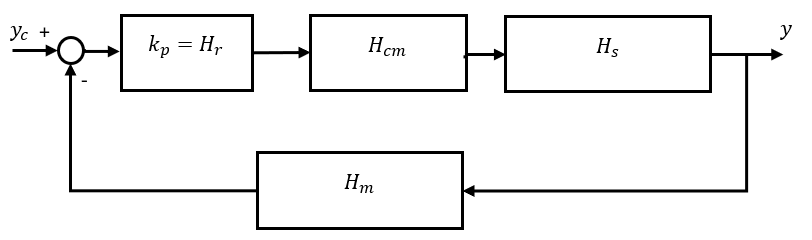

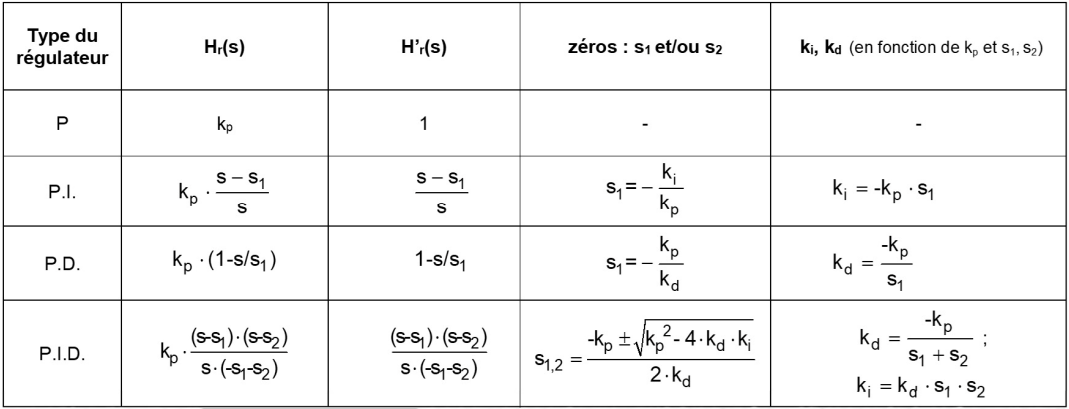

clc; clear; close all;
numHcm = [0 0 1];
denHcm = [0 0 1];

numHs = [0 0 1];
denHs = [1 3 -10];

numHm=[0 0 20];
denHm=[0 0 1];

s1 = -1;   % Besoin pour : PI PD PID
s2 = 1;  % Besoin pour : PID

% Hpr PD
numHprD=[-1 s1];
denHprD=[0 s1];

% Hpr PI
numHprI=[0 1 -s1];
denHprI=[0 1 0];

% Hpr PID
numHprPID=[1 (-1*(s2+s1)) (s1*s2)];
denHprPID=[0 (-1*(s1+s2)) 0]

denHprPID =      0     0     0


## Selection du type de régulation

falseInd = 'P'

falseInd = 'P'

falseInd = 'PI'

falseInd = 'PI'

falseInd = 'PD'

falseInd = 'PD'

trueInd = 'PID'

trueInd = 'PID'

## Avec/Sans pérturbation

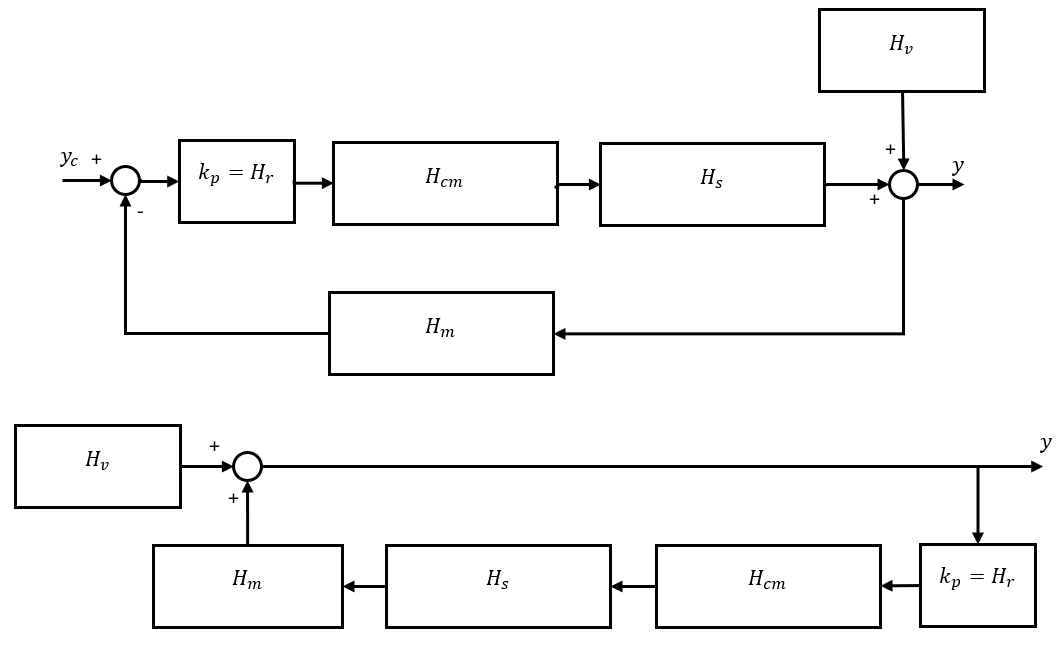

perturb = false

perturb = logical
   0


if perturb    
    numHV=[1];
    denHV=[1];
end


## P

[numHLP,denHLP]=series(numHcm,denHcm,numHs,denHs);
[numHLP,denHLP]=series(numHLP,denHLP,numHm,denHm);



figure ('Name','Lieu des pôles rég. P');
sgrid('new')

disp('Reg P')

Reg P


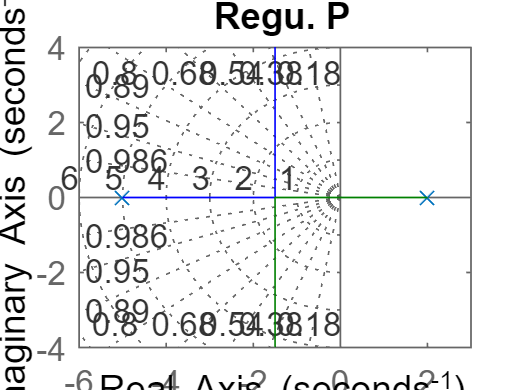

rlocus(numHLP,denHLP)
title('Regu. P')


if strcmp(trueInd,'P')
    [kp,poles]=rlocfind(numHLP,denHLP);
end

## PD

if (strcmp(trueInd,'PD'))
    [numHLPD,denHLPD]=series(numHLP,denHLP,numHprD,denHprD);

    if strcmp(trueInd,'PD')
        disp('Reg PD')
        sgrid('new')
        %X=linspace(0,5000,20000);
        rlocus(numHLPD,denHLPD)
        title('Regu. PD')
        [kp,poles]=rlocfind(numHLPD,denHLPD);
    end
end

## PI

if (strcmp(trueInd,'PI'))
    [numHLPI,denHLPI]=series(numHLP,denHLP,numHprI,denHprI);

    if strcmp(trueInd,'PI')
        disp('Reg PI')
        sgrid('new')
        %X=linspace(0,10,200);
        rlocus(numHLPI,denHLPI)
        title('Regu. PI')
        [kp,poles]=rlocfind(numHLPI,denHLPI);
    end
end


## PID

Reg PID


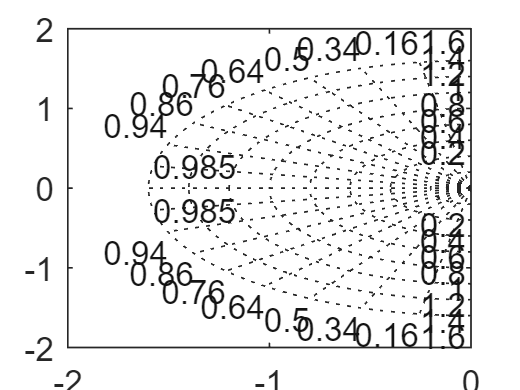

Error using tf (line 303)
The denominators specified in the "Denominator" property must be nonzero vectors.
Error in rlocus (line 89)
    sys = tf(num,den);

if strcmp(trueInd,'PID')
    disp('Reg PID')
    [numHLPID,denHLPID]=series(numHLP,denHLP,numHprPID,denHprPID);
    
    %X=linspace(0,5000,20000);
    sgrid('new')
    rlocus(numHLPID,denHLPID)
    title('Regu. PID')
    [kp,poles]=rlocfind(numHLPID,denHLPID);
end

## Réponce indiciel

figure ('Name','Réponse indicielle par rapport à la consige');
sgrid('new')

 switch trueInd
    
    case 'P'
        [numH1, denH1]=series(kp*numHcm,denHcm,numHs,denHs);
        [numHbc,denHbc]=feedback(numH1,denH1,numHm,denHm);
        step(numHbc,denHbc)
        title('Step response P')
        
    case 'PI'
        [numH1, denH1]=series(kp*numHprI,denHprI,numHcm,denHcm);
        [numH1, denH1]=series(numH1,denH1,numHs,denHs);
        [numHbc,denHbc]=feedback(numH1,denH1,numHm,denHm);
        step(numHbc,denHbc)
        title('Step response PI')
        
    case 'PD'
        [numH1, denH1]=series(kp*numHprD,denHprD,numHcm,denHcm);
        [numH1, denH1]=series(numH1,denH1,numHs,denHs);
        [numHbc,denHbc]=feedback(numH1,denH1,numHm,denHm);
        step(numHbc,denHbc)
        title('Step response PD')
        
    case 'PID'
        [numH1, denH1]=series(kp*numHprD,denHprD,numHcm,denHcm);
        [numH1, denH1]=series(numH1,denH1,numHprI,denHprI);
        [numH1, denH1]=series(numH1,denH1,numHs,denHs);
        [numHbc,denHbc]=feedback(numH1,denH1,numHm,denHm);
        step(numHbc,denHbc)
        title('Step response PID')
        
    otherwise
        disp('other value')
    
 end


## Réponce indiciel avec perturbation

if perturb
 
    figure ('Name','Réponse indicielle par rapport à la perturbation');
    sgrid('new')
    
    [numH2, denH2]=series(numH1,denH1,numHm,denHm);
    [numHbp,denHbp]=feedback([1],[1],numH2,denH2);
    [numHbp,denHbp]=series(numHbp,denHbp,numHV,denHV);
    
    step(numHbp,denHbp)
    title('Step response with disturbance')

end